clear; close all; clc;
k_stop = 1; delta_min = -1; delta_max = 3;

% define hardening spring hinge moment

% not deisred as it starts at non zeoro at the linits
HM = @(delta_f) -k_stop * delta_f * (heaviside(delta_f - delta_max) + heaviside(delta_min - delta_f));
% uses heavisides (easy to swap to sigmoids)
HM = @(delta_f) -k_stop * ((heaviside(delta_min - delta_f) * (delta_f - delta_min)) +  (heaviside(delta_f - delta_max) * (delta_f - delta_max)))

HM = function_handle with value:
    @(delta_f)-k_stop*((heaviside(delta_min-delta_f)*(delta_f-delta_min))+(heaviside(delta_f-delta_max)*(delta_f-delta_max)))


% uses min and max (more elegant to put in paper)
HM = @(delta_f) -k_stop * (min(0,delta_f - delta_min) +  max(0,delta_f - delta_max))

HM = function_handle with value:
    @(delta_f)-k_stop*(min(0,delta_f-delta_min)+max(0,delta_f-delta_max))


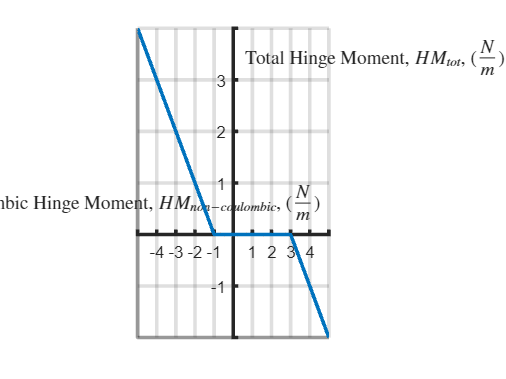



foo = fplot(@(delta_f) HM(delta_f));

grid on; % turn of gid on the figure

% get the current axies
ax = gca;


% make everything look all thick and nice
%set(gca,"LineWidth", 2); % make axies look thick
ax.LineWidth = 2;

hold on;
%lines = findobj(ax,'-property', 'LineStyle'); % get all things with a line style (use this for editing anything plots that have lines)
lines = findobj(ax,'-regexp' ,'Type', "line"); % get all lines or things that are called something like line (use this for only editiing plots that are lines)
set(lines, 'LineWidth', 2); % Set the line width for all lines


% label x and y axies
xlabel("Noncoulombic Hinge Moment, $HM_{non-coulombic}$, ($\frac{N}{m}$)",Interpreter="latex");
ylabel("Total Hinge Moment, $HM_{tot}$, ($\frac{N}{m}$)",Interpreter="latex");

% set the axises to cross at the origin
ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; % Set axes to cross at zero
ax.Box = "off"; % turn off  the box around the figure

% display ticks at every visible integer
xticks(ceil(ax.XLim(1)):floor(ax.XLim(2))); % plot x ticks on every integer being displayed
yticks(ceil(ax.YLim(1)):floor(ax.YLim(2))); % plot y ticks on every integer being displayed